# Quadcopter Project

This example shows how to use Simulink® to model a quadcopter, based on the Parrot® series of mini-drones. 

- To manage the model and source files, it uses [Project Management](docid:simulink_doccenter#project-management). 

- To show the quadcopter in a three-dimensional environment, it uses Simulink® 3D Animation™.

- For the collaborative development of a flight simulation application, it provides an implementation of the Flight Simulation application template.

This example works with the [Simulink Support Package for Parrot Minidrones](https://www.mathworks.com/hardware-support/parrot-minidrones.html).

**Note:** To successfully run this example you must have a C/C++ compiler installed.

## Open the Quadcopter Project

Run the following command to create and open a working copy of the project files for this example:

openProject('asbQuadcopter');

## Quadcopter Physical Characteristics

The following schematic shows the quadcopter physical characteristics:

- Axis

- Mass and Inertia

- Rotors

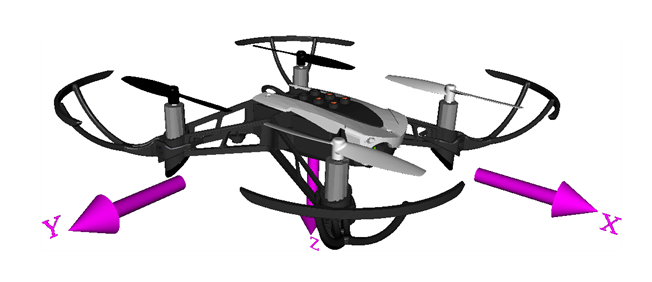

**Axis**

The quadcopter body axis is centered in the center of gravity.

- The *x*-axis starts at the center of gravity and points in the direction along the nose of the quadcopter.

- The *y*-axis starts at the center of gravity and points to the right of the quadcopter.

- The *z*-axis starts at the center of gravity and points downward from the quadcopter, following the right-hand rule.

**Mass and Inertia**

We assume that the whole body works as a particle. The file `vehicleVars` contains the values for the inertia and mass.

**Rotors**

- Rotor #1 rotates positively with respect to the *z*-axis. It is located parallel to the *xy*-plane, -45 degrees from the *x*-axis.

- Rotor #2 rotates negatively with respect to the body's *z*-axis. It is located parallel to the *xy*-plane, 455 degrees from the *x*-axis.

- Rotor #3 has the same rotation direction as rotor #1. It is located parallel to the *xy*-plane, 135 degrees from the *x*-axis.

- Rotor #4 has the same rotation direction as rotor #2. It is located parallel to the *xy*-plane, -135 degrees from the *x*-axis.

This example uses the Multirotor block in the Aerospace Blockset. The block is based on the approach defined by Prouty[1] and adapted to a heavy-lift quadcopter by Pounds et al[2].

## Control

For control, the quadcopter uses a complementary filter to estimate attitude, and Kalman filters to estimate position and velocity. The example implements:

- A PID controller for pitch/roll control

- A PD controller for yaw

- A PD controller for position control in North-East-Down coordinates

The `controllerVars` file contains variables pertinent to the controller. The `estimatorVars` file contains variables pertinent to the estimator.

The example implements the controller and estimators as model subsystems, enabling several combinations of estimators and controllers to be evaluated for design.

To provide inputs to the quadcopter (in pitch, roll, yaw, North (X), East (Y), Down (Z) coordinates ), use one of the following and change the `VSS_COMMAND` variable in the workspace:

- A Signal Editor block

- A joystick

- Previously saved data

- Spreadsheet data

## Sensors

The example uses a set of sensors to determine its states:

- An Inertial Measurement Unit (IMU) to measure the angular rates and translational accelerations.

- A camera for optical flow estimation.

- A sonar for altitude measurement.

The example stores the characteristics for the sensors in the file `sensorVars`. To include sensor dynamics with these measurements, you can change the `VSS_SENSORS` variable in the workspace.

## Environment

The models implement several Aerospace Blockset™ environment blocks, including those for atmosphere and gravity models. To include these models, you can change the `VSS_ENVIRONMENT` variable in the workspace to toggle between variable and fixed environment models.

## Linearization

The model uses the `trimLinearizeOpPoint` to linearize the nonlinear model of the quadcopter using Simulink® Control Design™.

## Testing

To make sure that the trajectory generation tool works properly, the example implements a test in the `trajectoryTest` file. For more information, see [Get Started with Simulink Control Design](docid:slcontrol_doccenter#gscat).

## Visualization

You can visualize the variables for the quadcopter in one of the following ways:

- Using Simulation Data Inspector.

- Using the flight instrument blocks.

- Toggling between the different visualization variant subsystems. You can toggle between the different variant subsystems by changing the `VSS_VISUALIZATION` variable. Note that one of these variants is a FlightGear animation. To use this animation, you must add a FlightGear compatible model of the quadcopter to the project. The software does not include this model.

## Trajectory generation

A trajectory generation tool, using the Dubin method, creates a set of navigational waypoints. To create a trajectory with a set of waypoints this method uses a set of poses defined by position, heading, turn curvature, and turn direction.

To start the tool, ensure that the project is open and run:

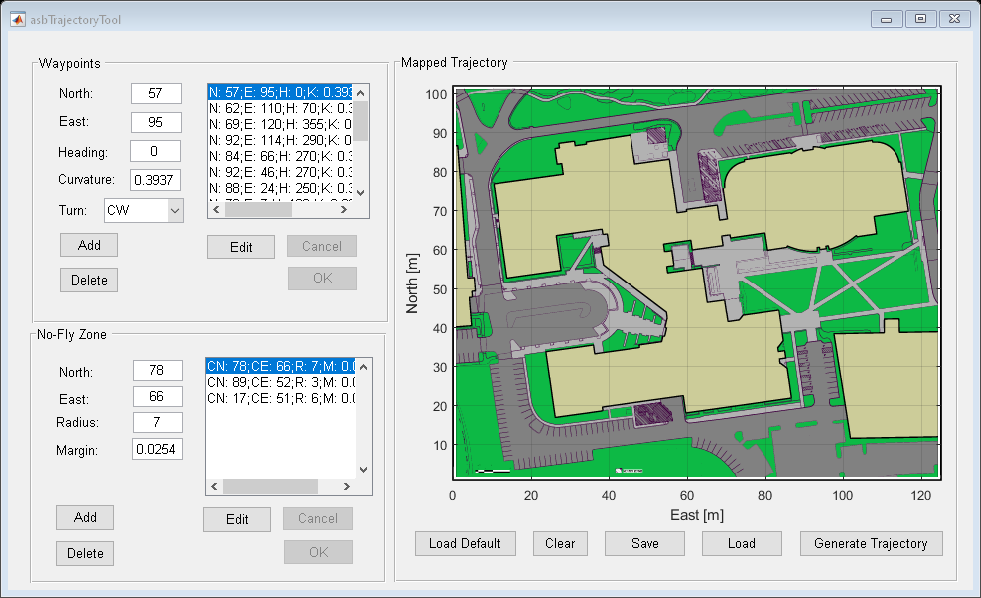

asbTrajectoryTool

The following interface displays:

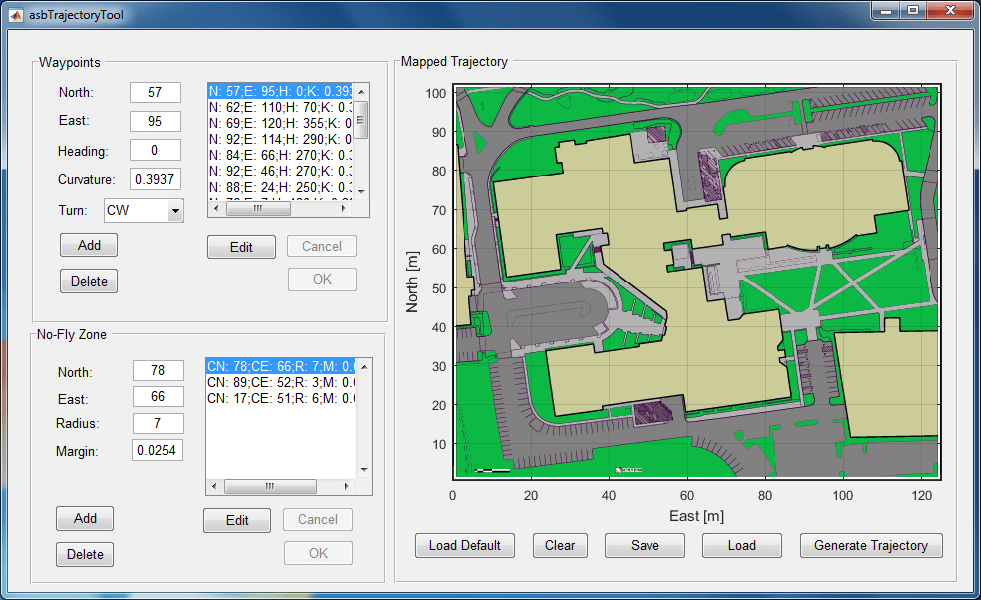

The interface has several panels:

**Waypoints**

This panel describes the poses the trajectory tool requires. To define these poses, the panel uses text boxes:

- **North** and **East** (position in meters)

- **Heading** (degrees from North)

- **Curvature** (turning curvature in meters^-1)

- **Turn** (direction clockwise or counter-clockwise)

A list of poses appears in the waypoint list to the right of the text boxes.

To add a waypoint, enter pose values in the edit boxes and click **Add**. The new waypoint appears in the waypoint list in the same panel.

To edit the characteristics of a waypoint, select the waypoint in the list and click **Edit**. The characteristics of the waypoints display in the edit boxes. Edit the characteristics as desired, then click **OK**. To cancel the changes click **Cancel**.

To delete a waypoint, in the waypoint list, select the waypoint and click **Delete**.

**No-Fly Zone**

The panel defines the location and characteristics of the no-fly zones. To define the no-fly zone, the panel uses text boxes:

- **North** and **East** (position in meters)

- **Radius** (distance in meters)

- **Margin** (safety margin in meters)

Use the **Add**, **Delete**, **Edit**, **OK**, and **Cancel** buttons in the same way as for the Waypoints panel.

**Mapped Trajectory**

This panel plots the trajectory over the Apple Hill campus aerial schematic based on the waypoints and no-fly zone characteristics.

To generate the trajectory, add the waypoint and no-fly zone characteristics to the respective panels, then click **Generate Trajectory**.

To save the trajectory that is currently in your panel, click the **Save** button. This button only saves your last trajectory.

To load the last saved trajectory, click **Load**.

To load the default trajectory, press the **Load Default** button.

To clear the values in the waypoint and no-fly zone panel, click **Clear**.

The default data contains poses for specific locations at which the toy quadcopter uses its cameras so the pilot on the ground can estimate the height of the snow on the roof. Three no-fly zones were defined for each of the auxiliary power generators, so in case there is a failure in the quadcopter, it does not cause any damage to the campus infrastructure.

When the example generates the trajectory for the default data, the plot should appear as follows: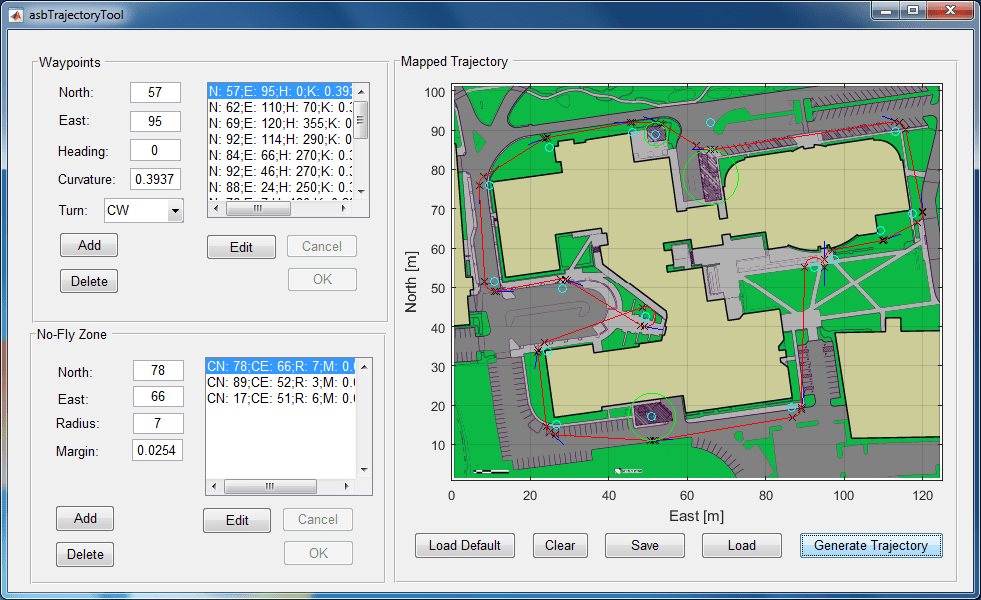

The red line represents the trajectory, black **x** markers determine either a change in the trajectory or a specific pose. Blue lines that represent the heading for that specific waypoint accompany specific poses. No-fly zones are represented as green circles.

If you have a Simulink 3D Animation license, you can also view the trajectory in a 3-D representation of the Apple Hill campus:

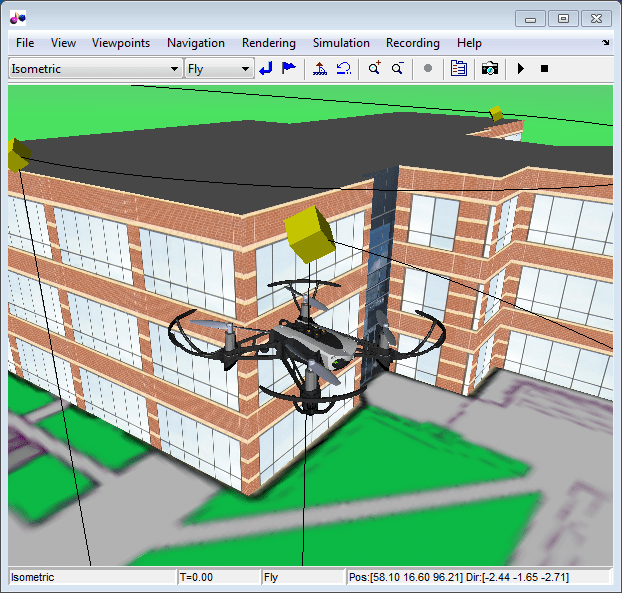

**Note:** For visualization reasons the 3D representation of the quadcopter is not at the same scale as the environment and the rotor speeds have been lowered to removing aliasing.

## References

[1] Prouty, R. Helicopter Performance, Stability, and Control. PWS Publishers, 2005.

[2] Pounds, P., Mahony, R., Corke, P. Modelling and control of a large quadrotor robot. Control Engineering Practice. 2010.

Copyright 2013-2023 The MathWorks, Inc.